% формирование массива данных по Зеленоградску
clear

d = dir('C:\Users\user\MATLAB Drive\1Exponenta\01.03_train one GRS\data_zelenograds');

d(1:3) = []; % обнуление 
t7 = []; % создание пустого массива

for i = 1:numel(d)
    disp(i) % демо считывания данных по месяцам
    str = d(i).folder +"\"+ d(i).name; % считываем имя файла в директории d
    [a,txt] = readfile_all(str); % читаем файл, к которому обращаемся
    b = txt(3:end,2); % заменили формат, в котором указано время (часы), на читаемый 
    B = ismissing(b);% заменили формат, в котором указано время (часы), на читаемый 
    b(B) = [];% заменили формат, в котором указано время (часы), на читаемый 
    c = categorical(b);% заменили формат, в ктором указано время (часы), на читаемый 
    b1 = double(c);% заменили формат, в котором указано время (часы), на читаемый 
    t7 = [t7; [b1, a(:,1:5)]];% 
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12



b = t7(:,end) == 0;
B = diff(b);
f = find(B);
t7_1 = t7(1:f(1),:);
t7_2 = t7(f(end)+1:end,:);
idx_1 = f(1);
idx_2 = f(end)+1;


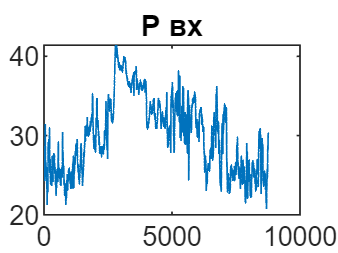

% plot(t7);
% plot(t7(:,1));
% title("Часы")
plot(t7(:,2));
title("P вх")

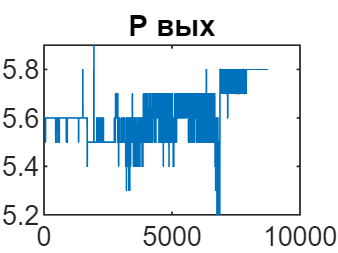

plot(t7(:,3));
title("P вых")

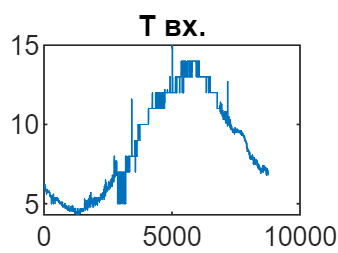

plot(t7(:,4));
title("Т вх.")

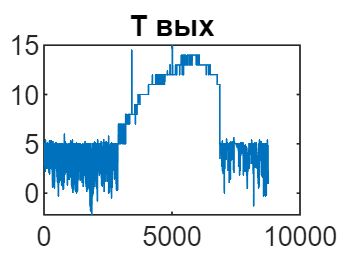

plot(t7(:,5));
title("Т вых")

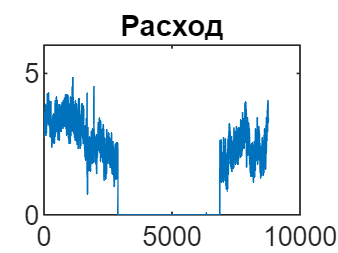

plot(t7(:,6));
title("Расход")

save data_zelenograds t7_1 t7_2 idx_1 idx_2

function [t7,txt] = readfile_all(str)
[t7,txt] = xlsread(str,'Лист1');
s = all(isnan(t7));
t7(:,s) = [];
b = all(isnan(t7),2);
t7(b,:) = [];
end